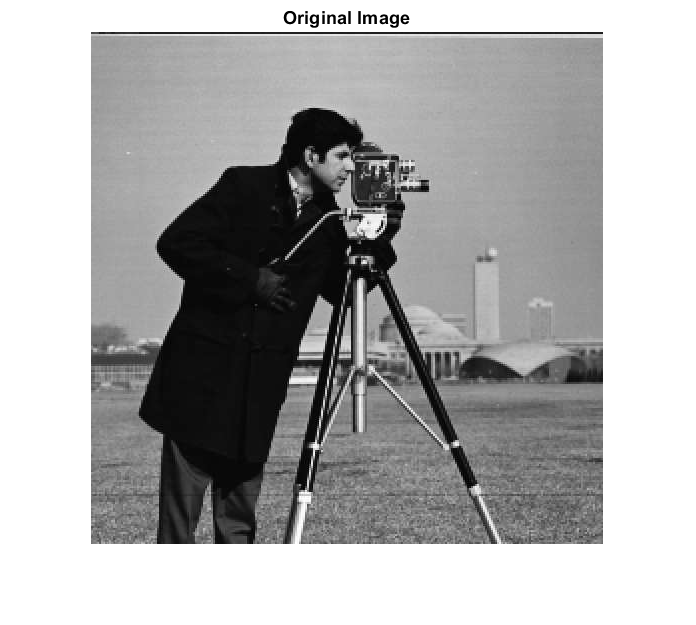

clear all;
close all;
clc;

img = imread('cameraman.jpg');
imshow(img);
title('Original Image');

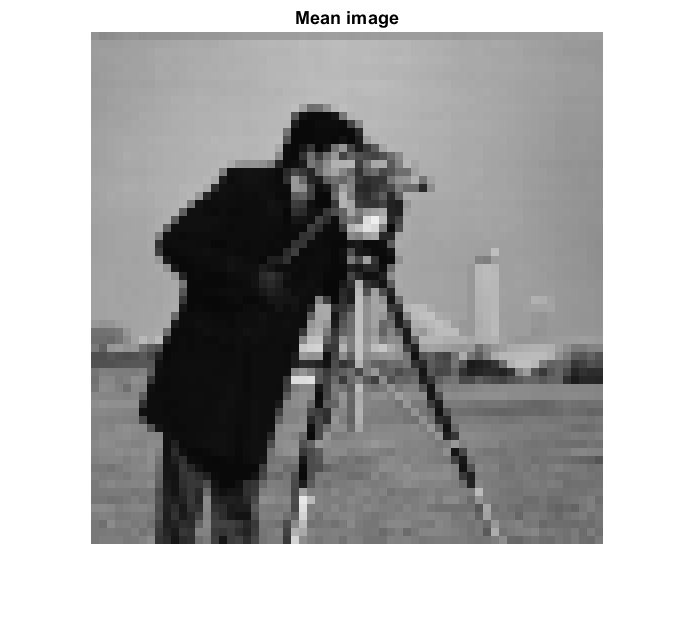

fun = @(block_struct)mean2(block_struct.data) *...
    ones(size(block_struct.data));
mean_img_double = blockproc(img, [8 8], fun);
imshow(uint8(mean_img_double));
title('Mean image');

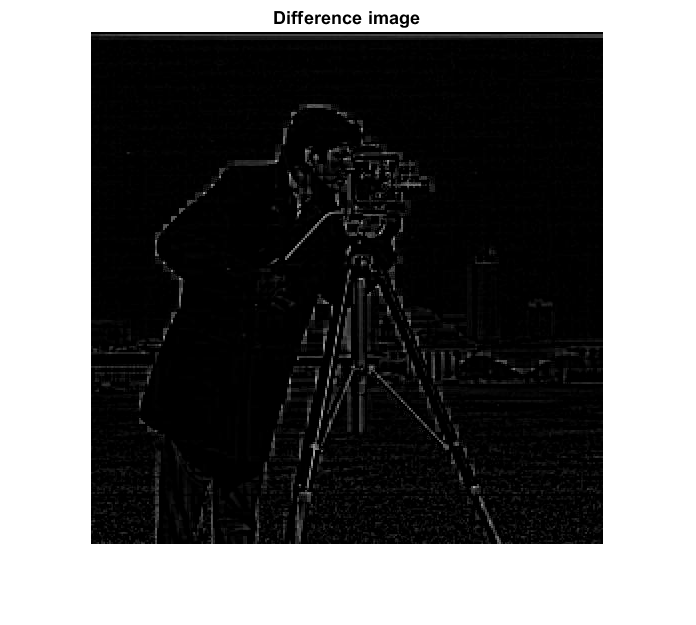

diff_img_uint8 = uint8(double(img) - mean_img_double);
imshow(diff_img_uint8);
title('Difference image');

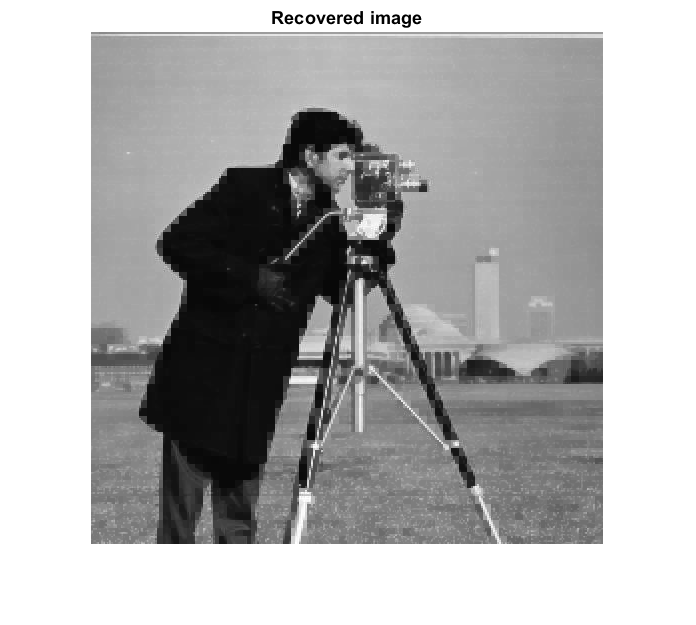

[zipped_mean, zipped_diff, info_mean, info_diff] = diff_coder(img);
%----------------------------------------
% After doing the encoding and try to decode:
img_recover = diff_decoder(zipped_mean, zipped_diff, info_mean, info_diff);
imshow(img_recover);
title('Recovered image');

peaksnr = psnr(img_recover, img)

peaksnr = 24.1169